xjs = [0:5].*pi./10; % training points
g = @(x) 1-cos(x); % ground truth
yjs = g(xjs);
relu = @(w)max(w,0);
drelu = @(w)ones(size(w)).*sign(relu(w));
A = [xjs' -1.*ones(length(xjs),1)];
[As,Bs] = meshgrid(-1:0.1:1);

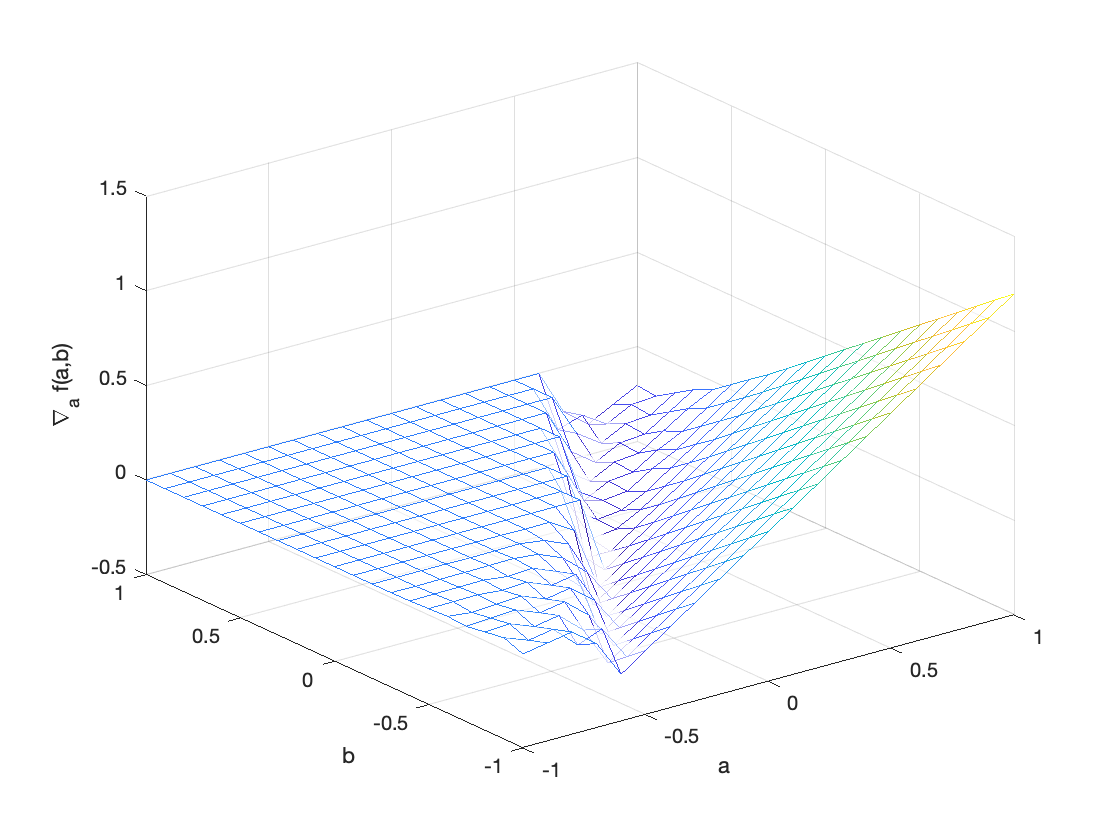

Fas = zeros(length(As),length(Bs));
for i = 1:length(As)
    for j = 1:length(Bs)
        Fas(i,j) = grad_a(As(i,j),Bs(i,j),xjs,yjs);
    end
end
figure;
s = mesh(As,Bs,Fas,'FaceAlpha','0.5');
xlabel('a');ylabel('b');zlabel('\nabla_a f(a,b)');
saveas(gcf,'figures/grad_a.png');

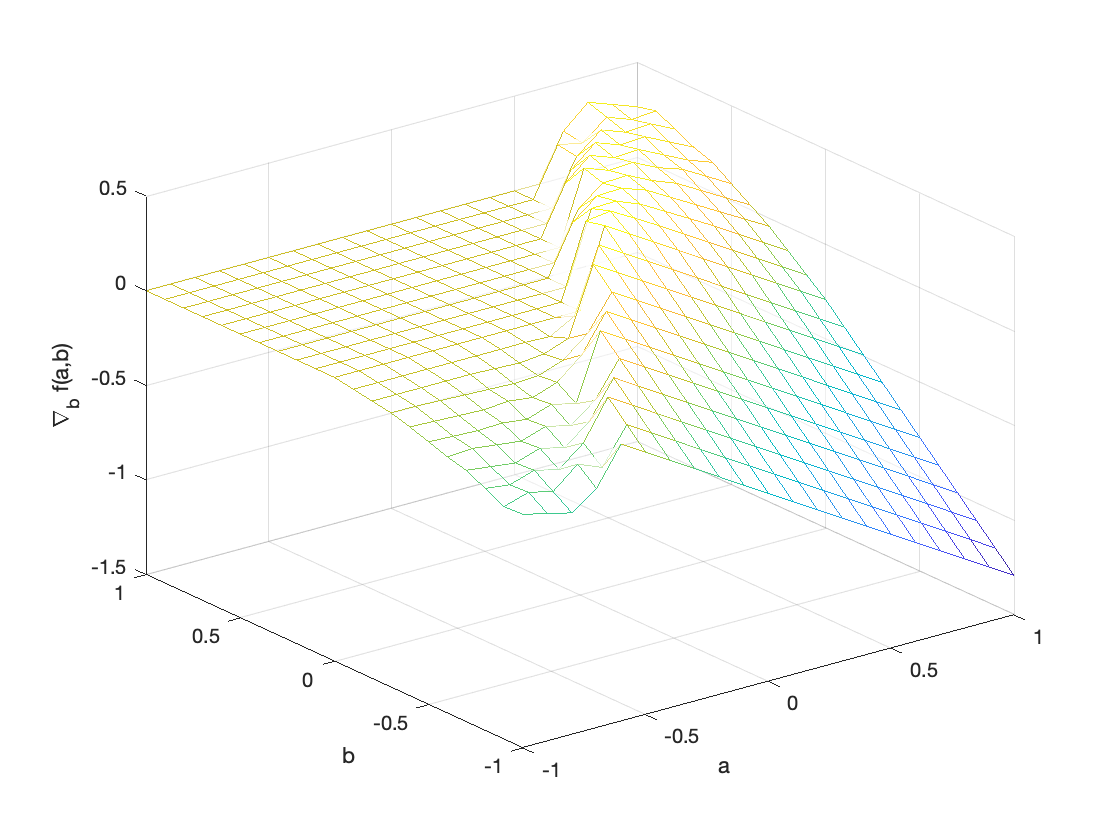

Fbs = zeros(length(As),length(Bs));
for i = 1:length(As)
    for j = 1:length(Bs)
        Fbs(i,j) = grad_b(As(i,j),Bs(i,j),xjs,yjs);
    end
end
figure;
s = mesh(As,Bs,Fbs,'FaceAlpha','0.5');
xlabel('a');ylabel('b');zlabel('\nabla_b f(a,b)');
saveas(gcf,'figures/grad_b.png');

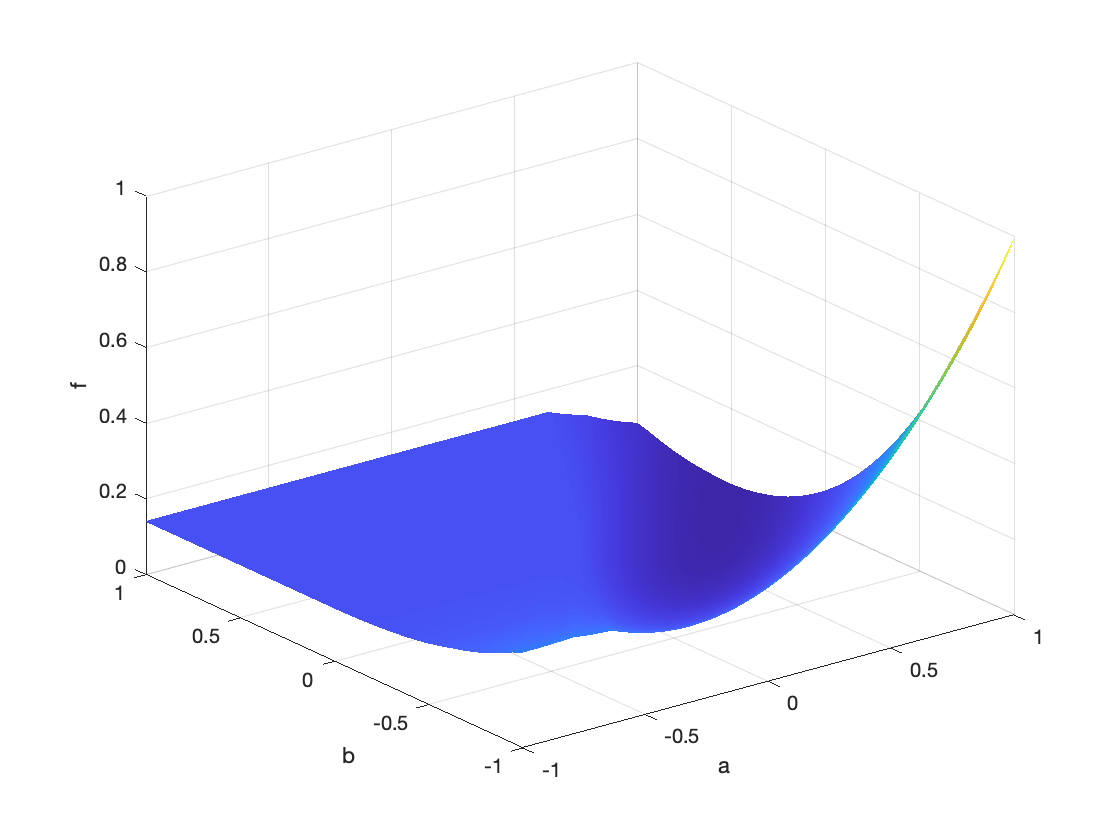

[As,Bs] = meshgrid(-1:0.001:1);
Fcs = zeros(length(As),length(Bs));
for i = 1:length(As)
    for j = 1:length(Bs)
        Fcs(i,j) = f(As(i,j),Bs(i,j),xjs,yjs);
    end
end
figure;
s = mesh(As,Bs,Fcs,'FaceAlpha','0.5');
xlabel('a');ylabel('b');zlabel('f');

%saveas(gcf,'figures/f.png');

[minsval,minsindex] = min(Fcs)

minsval =     0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405    0.1405


minsindex =         1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001        1001


[value,index] = min(minsval)

value = 3.6329e-04

index = 1862

Fcs(minsindex(index),1862)

ans = 3.6329e-04

As(minsindex(index),index)

ans = 0.8610

Bs(minsindex(index),index)

ans = 0.3730

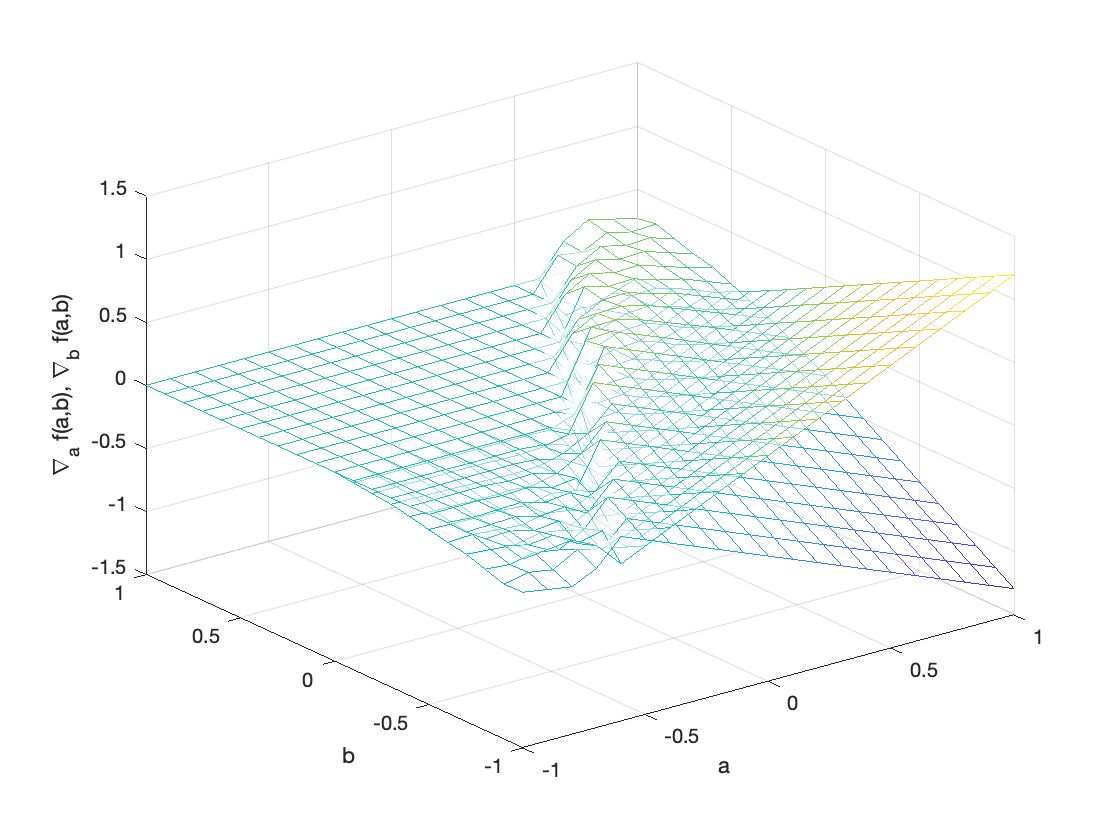

figure;
s = mesh(As,Bs,Fas,'FaceAlpha','0.5');
xlabel('a');ylabel('b');zlabel('\nabla_a f(a,b), \nabla_b f(a,b)');
hold on;
mesh(As,Bs,Fbs,'FaceAlpha','0.5');
saveas(gcf,'figures/ab.png');

%mesh(As,Bs,Fes-1,'FaceAlpha','0.5');
%saveas(gcf,'figures/overlay.png');

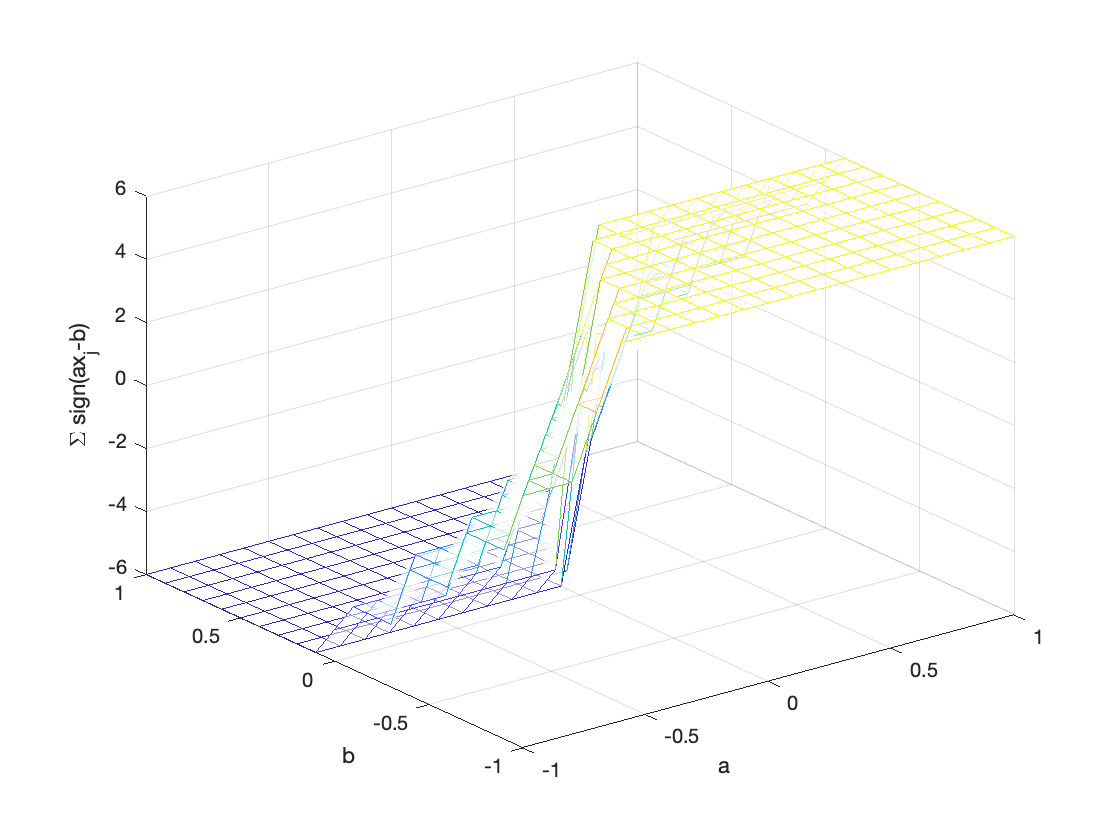

[As,Bs] = meshgrid(-1:0.1:1);
diffs = zeros(length(As),length(Bs));
for i = 1:length(As)
    for j = 1:length(Bs)
        total = zeros(length(A),1);
        for k = 1:length(A)
            c = xjs(k);
            total(k) = sign(As(i,j)*c-Bs(i,j));
        end
        diffs(i,j) = sum(total);
    end
end
figure;
s = mesh(As,Bs,diffs,'FaceAlpha','0.5');
xlabel('a');ylabel('b');zlabel('\Sigma sign(ax_j-b)','Interpreter',"tex");
saveas(gcf,'gradient_sign.png');

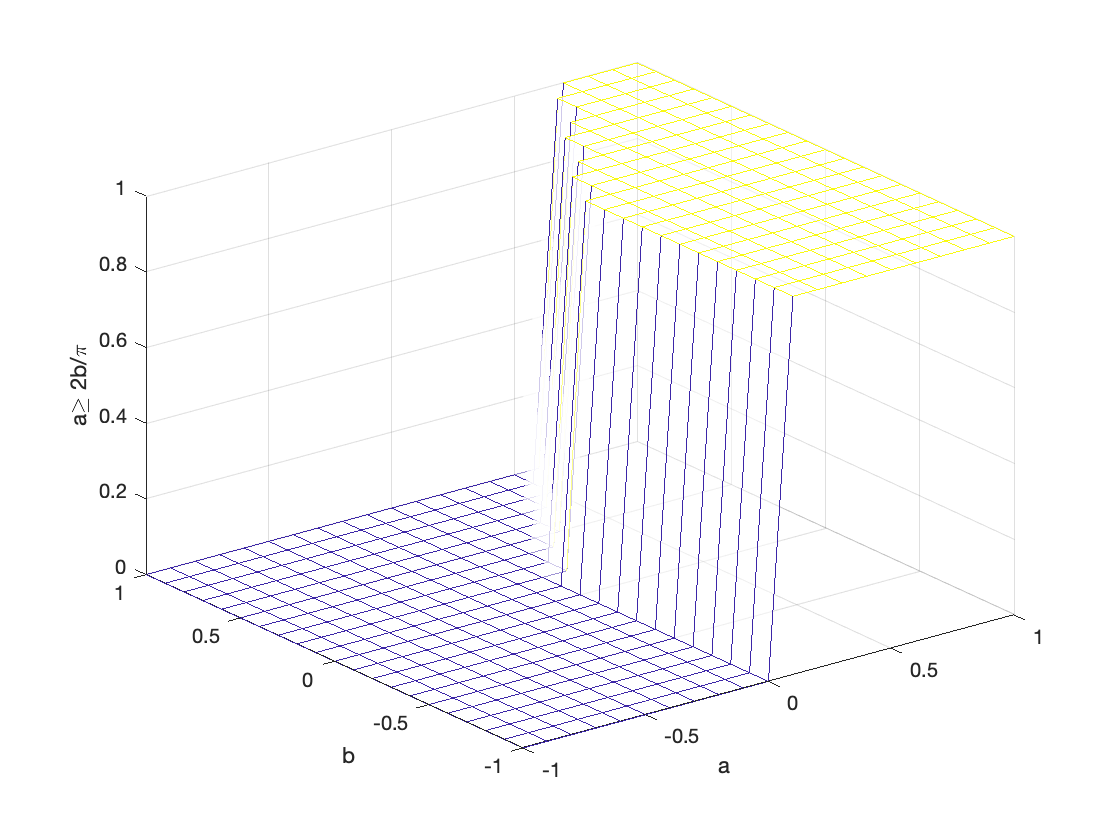

ratio = 1.0564

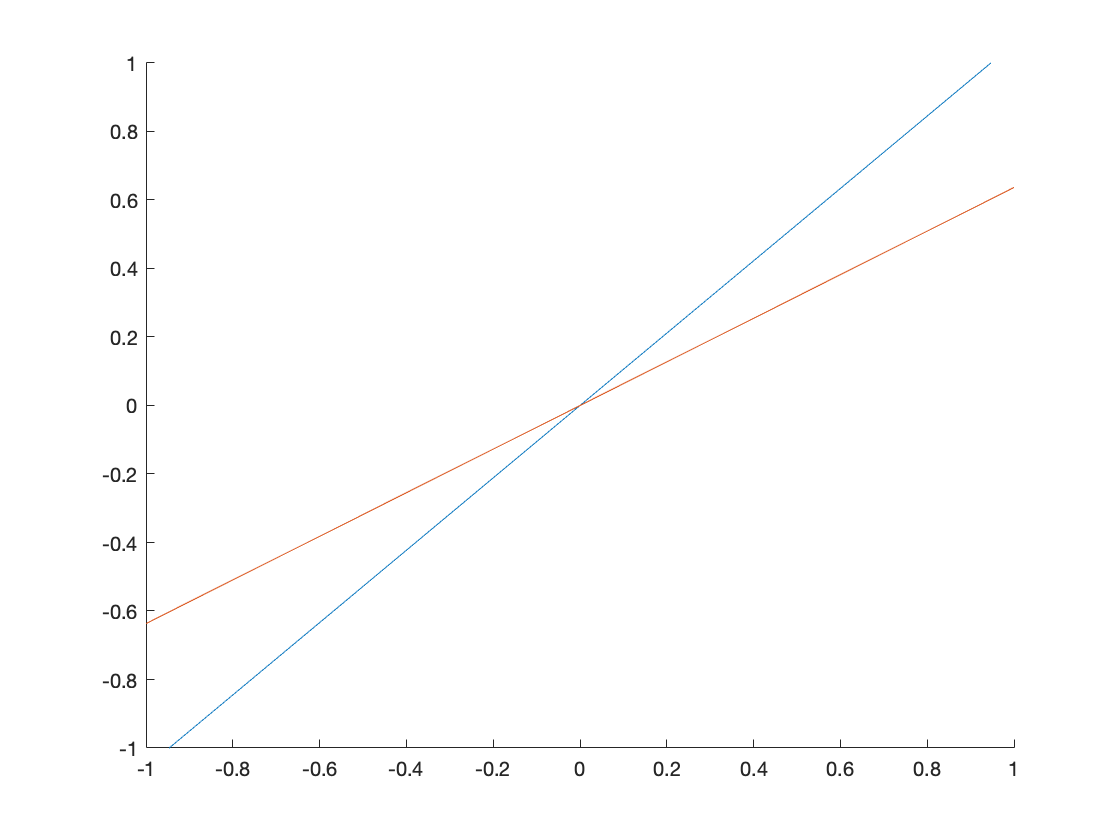

[As,Bs] = meshgrid(-1:0.1:1);
Fes = zeros(length(As),length(Bs));
for i = 1:length(As)
    for j = 1:length(Bs)
        Fes(i,j) = (As(i,j)>=2*Bs(i,j)/pi)&&As(i,j)>0;
    end
end
figure;
s = mesh(As,Bs,Fes,'FaceAlpha','0.5');
xlabel('a');ylabel('b');zlabel('a\geq 2b/\pi');
saveas(gcf,'figures/cons.png');